# **LPV-MPC: Frozen Trajectory Approach**

This interactive script demonstrates the Frozen (Gain-Scheduling) approach for estimating the LPV scheduling parameters using a Two Tank system.

The nonlinear dynamics are governed by Torricelli's law. We embed the nonlinearities inside bounded scheduling parameters by extracting $\rho_1 =\frac{1}{\sqrt{h_1 }}$ and $\rho_2 =\frac{1}{\sqrt{h_2 }}$.

## Initialization

First, we build the base CHRONOS MPC structure, initializing the system with the dynamic matrices "frozen" at the starting condition.

% Tank area and gravity value
Ab = 1; g = 9.81; h1 = 0.45; h2 = 0.45; Ts = 0.01;
N = 10;
mpc = init_mpc(N);

% LTI system frozen at current state vector
A = [-sqrt(2*g)*sqrt(h1)/(Ab*h1) 0; sqrt(2*g)*sqrt(h1)/(Ab*h1) -sqrt(2*g)*sqrt(h2)/(Ab*h2)];
B = [1/Ab; 0];
mpc = init_mpc_dynamics(mpc,eye(2)+Ts*A,Ts*B,0);
mpc = init_mpc_output(mpc,[0 1],[],[]);

% Constraints and Costs
mpc = init_mpc_state_cnstr(mpc,0.01*ones(mpc.nx,1), 1*ones(mpc.nx,1));
mpc = init_mpc_u_cnstr(mpc,0,10);
mpc = init_mpc_ter_ingredients_dlqr(mpc,diag([30 30]),1,0);

## Simulation Setup 

We define the base scheduling function and the interface handle that constructs the affine matrix for a single time step. Notice that we only created a ``compute_A`` function because the qLPV behavior is embedded entirely within the A matrix.

tsim = 5; 
Sim_samples = tsim/Ts;
time = 0:Ts:tsim-Ts;

r = zeros(1,Sim_samples);
r(time<=2.5) = 0.7; r(time>2.5) = 0.25;
tau = 0.1; xf = h2;        

n = mpc.N;
n_rho = 2;

my_sched_fun = @(x) [1/sqrt(max(x(1), 1e-4)); 1/sqrt(max(x(2), 1e-4))];
k_tank = sqrt(2*g)/Ab;
compute_A = @(rho) eye(2) + Ts * [-k_tank*rho(1), 0; k_tank*rho(1), -k_tank*rho(2)];

clear rf_dat h1_dat h2_dat u_dat t_dat
x_prev = [h1; h2]; u_prev = 3.7;
mpc = build_chronos_mpc(mpc,x_prev,u_prev);

## The Frozen Estimation Loop 

At the core of the loop, the workflow is: 

Estimate Trajectory -> Build Matrices -> Update Solver. 

Now, we actually call the scheduling trajectory function ``compute_schedul_frozen``. In this method, the solver assumes that the system parameters will remain constant over the entire prediction horizon. Mathematically, it evaluates the nonlinear scheduling function $f_\rho(x)$ at the current measured state $x(k)$ and *freezes* it:


$$\hat{P}_k = [ \rho(k), \rho(k), \cdots, \rho(k)] .$$


An intuitive view of this method is presented in the following:

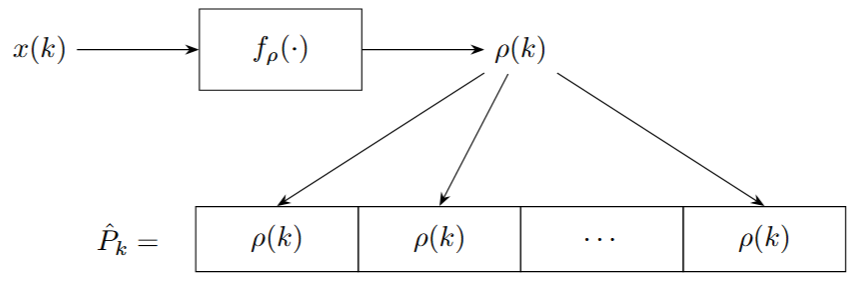

The code extract with the estimation loop and MPC computation is presented:

for k = 1:Sim_samples
    h1 = x_prev(1); h2 = x_prev(2);
    xf = xf + Ts*(-xf/tau+r(k)/tau);
    x_ref = [xf;xf];
    
    tic;
    % Estimate trajectory (FROZEN)
    Pk = compute_schedul_frozen(mpc, x_prev, my_sched_fun);
    
    % Build  matrices
    A_lpv = traj_mat(compute_A, Pk, n_rho, n);
    
    % Update and solve
    mpc = update_mpc_dynamics(mpc, A_lpv, [], []);
    [u_prev, iter, mpc] = mpc_solve(mpc, x_prev, u_prev, xf, x_ref, [], [], []);
    tk = toc;
    
    rf_dat(:,k) = xf; h1_dat(:,k) = h1; h2_dat(:,k) = h2; u_dat(k) = u_prev; t_dat(k) = tk;
    
    h1 = h1 + Ts*(u_prev/Ab-sqrt(2*g)*sqrt(h1)/Ab);
    h2 = h2 + Ts*(sqrt(2*g)*sqrt(h1)/Ab-sqrt(2*g)*sqrt(h2)/Ab);
    x_prev = [h1;h2];
end

## Results & Plots 

Finally, we plot the water height tracking performance, the control action (input mass flow) and its variation, along with the solver compute time per iteration. 

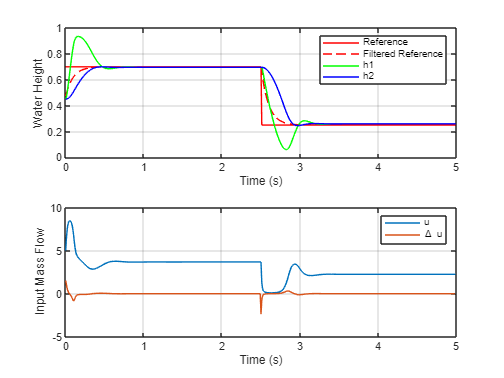

%% Plots
figure
ax1 = subplot(2,1,1);
plot(time,r,'r',time,rf_dat,'--r',time,h1_dat,'g',time,h2_dat,'b')
grid on
legend('Reference','Filtered Reference','h1','h2')
xlabel('Time (s)')
ylabel('Water Height')

ax2 = subplot(2,1,2);
plot(time,u_dat,time(1:end-1),diff(u_dat))
grid on
legend('u','\Delta u')
xlabel('Time (s)')
ylabel('Input Mass Flow')
linkaxes([ax1,ax2],'x')

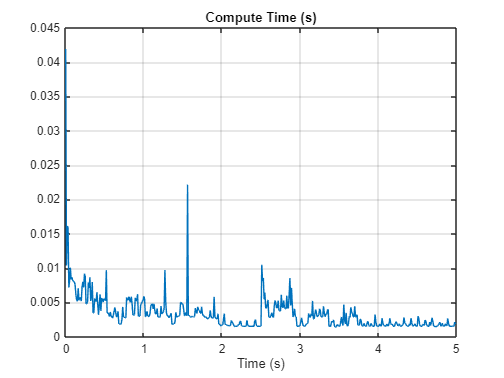


figure
plot(time,t_dat)
title('Compute Time (s)')
xlabel('Time (s)')
grid on